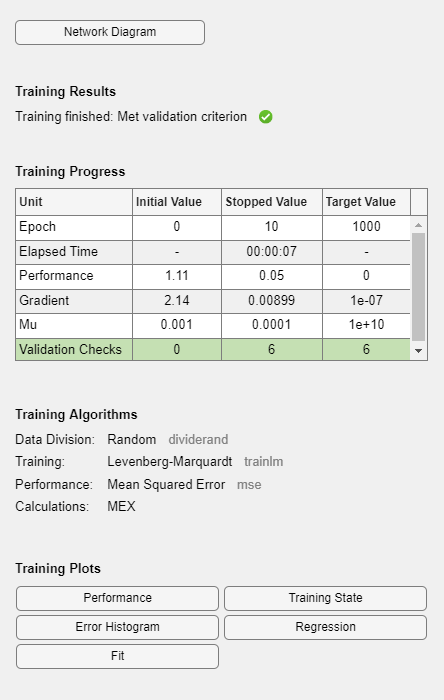

% Generate some dummy data
inputData = rand(3, 150); % 3 features, 150 samples
targetData = rand(1, 150); % 1 target variable, 150 samples

% Open Neural Network Fitting Tool
nftool

% Create a feedforward neural network
hiddenLayerSize = 10; % You can adjust this value
net = fitnet(hiddenLayerSize);

% Divide data into training and testing sets
net.divideParam.trainRatio = 0.7; % 70% for training
net.divideParam.valRatio = 0.15; % 15% for validation
net.divideParam.testRatio = 0.15; % 15% for testing

% Train the network
[net,tr] = train(net,inputData,targetData);

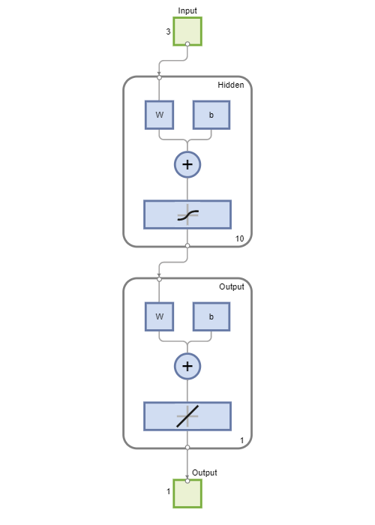


% Test the network
outputs = net(inputData);
errors = gsubtract(outputs,targetData);
performance = perform(net,targetData,outputs);

% View the network
view(net)